clear; clc;

%% Known Constants
KH2 = 0.14; KH3 = 440; KG2 = 15.1;

% Experimental total concentrations (mol/L)
Gtot = [0.25, 1, 2, 3, 4 ,5, 6, 7.5]' * 1e-3; % Guest total conc. (in M)
Htot = [0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5]' * 1e-3;      % Fixed Host total conc. (in M)
delta_obs_exp = [10.1965, 10.1959, 10.1949, 10.1950, 10.1945, 10.1935, 10.1927, 10.1916]'; % Replace with real data

%% Initial Guess: [logK1, logK2, δ_G, δ_G2, δ_HG, δ_HG2]
params0 = [-1, 2, 10.2, 10.18, 10.15, 10.15];
lb = [-4, -4, 10, 10, 9, 9];
ub = [10, 10, 10.2, 10.2, 10.3, 10.3];

%% Fit
options = optimoptions('lsqcurvefit','Display','iter','TolFun',1e-9,'TolX',1e-9);
[params_fit,~,~,~,~,~,~] = lsqcurvefit( ...
    @(p,x) model_guest_shift_stepwise(p,x,KH2,KH3,KG2), ...
    params0, [Htot Gtot], delta_obs_exp, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7       0.000129682                          0.00579
     1         14         1.399e-06        0.128797         9.02e-05      
     2         21         1.399e-06        0.524146         9.02e-05      
     3         28       1.18117e-06        0.131036         1.13e-05      
     4         35        1.0906e-06        0.262073         3.49e-06      
     5         42       9.11058e-07       0.0311028         2.21e-07      
     6         49       9.11058e-07        0.262073         2.21e-07      
     7         56        9.0875e-07       0.0655182         3.73e-07      
     8         63        9.0875e-07        0.131036         3.73e-07      
     9         70       9.07401e-07       0.0327591         9.76e-07      
    10         77       9.07185e-07       0.0655182         3.18e-07      



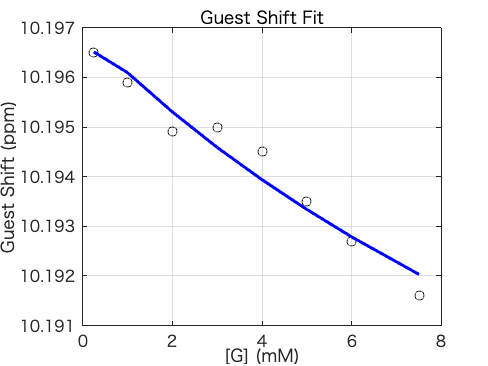


%% Plot
delta_fit = model_guest_shift_stepwise(params_fit,[Htot Gtot],KH2,KH3,KG2);
figure;
plot(Gtot*1e3, delta_obs_exp, 'ko'); hold on;
plot(Gtot*1e3, delta_fit, 'b-', 'LineWidth', 2);
xlabel('[G] (mM)'); ylabel('Guest Shift (ppm)');
title('Guest Shift Fit'); grid on;


fprintf('Fitted log10(K1) = %.2f\n', params_fit(1));

Fitted log10(K1) = -1.08


fprintf('Fitted log10(K2) = %.2f\n', params_fit(2));

Fitted log10(K2) = 3.10


fprintf('Fitted delta_G = %.4f\n', params_fit(3));

Fitted delta_G = 10.1970


fprintf('Fitted delta_G2 = %.4f\n', params_fit(4));

Fitted delta_G2 = 10.1668


fprintf('Fitted delta_HG = %.4f\n', params_fit(5));

Fitted delta_HG = 10.2553


fprintf('Fitted delta_HG2 = %.4f\n', params_fit(6));

Fitted delta_HG2 = 9.9614



% Calculate R-squared
SS_res = sum((delta_obs_exp - delta_fit).^2);
SS_tot = sum((delta_obs_exp - mean(delta_obs_exp)).^2);
R_squared = 1 - (SS_res / SS_tot);

% Display R-squared
fprintf('R-squared: %.6f\n', R_squared);

R-squared: 0.951681



%% === RESULTS ===
K1 = 10^params_fit(1);
K2 = 10^params_fit(2);
delta_G   = params_fit(3);
delta_G2  = params_fit(4);
delta_HG  = params_fit(5);
delta_HG2 = params_fit(6);

fprintf('\nFitted Parameters:\n');


Fitted Parameters:


fprintf('K1   (HG binding)    = %.2e M^-1\n', K1);

K1   (HG binding)    = 8.25e-02 M^-1


fprintf('K2   (HG + G -> HG2) = %.2e M^-1\n', K2);

K2   (HG + G -> HG2) = 1.26e+03 M^-1


fprintf('δ_G   (free G)       = %.4f ppm\n', delta_G);

δ_G   (free G)       = 10.1970 ppm


fprintf('δ_G2  (G dimer)      = %.4f ppm\n', delta_G2);

δ_G2  (G dimer)      = 10.1668 ppm


fprintf('δ_HG  (HG complex)   = %.4f ppm\n', delta_HG);

δ_HG  (HG complex)   = 10.2553 ppm


fprintf('δ_HG2 (HG₂ complex)  = %.4f ppm\n', delta_HG2);

δ_HG2 (HG₂ complex)  = 9.9614 ppm


fprintf('\nPoint-by-point species breakdown:\n');


Point-by-point species breakdown:


fprintf('%6s %6s %6s %6s %6s %6s %6s %8s\n', ...
    '[G]mM','G','G2','HG','HG2','δ_calc','Δδ');

 [G]mM      G     G2     HG    HG2 δ_calc     Δδ 


for i = 1:length(Htot)
    Ht = Htot(i); Gt = Gtot(i);
    x0 = [Ht/2, Gt/2, 1e-6*ones(1,5)];
    sol = fsolve(@(x) system_eqs_stepwise(x, Ht, Gt, KH2, KH3, KG2, K1, K2), ...
        x0, optimoptions('fsolve','Display','off'));

    G = sol(2); G2 = sol(7); HG = sol(3); HG2 = sol(4);
    denom = G + 2*G2 + HG + 2*HG2;

    delta_calc = model_guest_shift_stepwise(params_fit,[Ht Gt],KH2,KH3,KG2);
    delta_diff = delta_obs_exp(i) - delta_calc;

    fprintf('%6.3f %6.3f %6.3f %6.4f %6.4f %8.4f %+8.6f\n', ...
        Gt*1e3, G/denom, 2*G2/denom, HG/denom, 2*HG2/denom, ...
        delta_calc, delta_diff);
end

 0.250  0.993  0.006 0.0000 0.0013  10.1965 -0.000015
 1.000  0.971  0.028 0.0000 0.0001  10.1961 -0.000196
 2.000  0.946  0.054 0.0000 0.0002  10.1953 -0.000405
 3.000  0.923  0.077 0.0000 0.0003  10.1946 +0.000411
 4.000  0.901  0.098 0.0000 0.0003  10.1939 +0.000563
 5.000  0.882  0.117 0.0000 0.0004  10.1933 +0.000162
 6.000  0.864  0.135 0.0000 0.0005  10.1928 -0.000086
 7.500  0.840  0.160 0.0000 0.0006  10.1920 -0.000430


function delta_obs = model_guest_shift_stepwise(params, xdata, KH2, KH3, KG2)
    K1 = 10^params(1);
    K2 = 10^params(2);
    delta_G = params(3);
    delta_G2 = params(4);
    delta_HG = params(5);     % guest environment in HG
    delta_HG2 = params(6);    % guest environment in HG2

    N = size(xdata,1);
    delta_obs = zeros(N,1);

    for i = 1:N
        Ht = xdata(i,1);
        Gt = xdata(i,2);

        x0 = [Ht/2, Gt/2, 1e-6*ones(1,5)];
        sol = fsolve(@(x) system_eqs_stepwise(x, Ht, Gt, KH2, KH3, KG2, K1, K2), ...
                     x0, optimoptions('fsolve','Display','off'));
        G = sol(2); G2 = sol(7); HG = sol(3); HG2 = sol(4);

        num = G*delta_G + 2*G2*delta_G2 + HG*delta_HG + 2*HG2*delta_HG2;
        denom = G + 2*G2 + HG + 2*HG2;
        delta_obs(i) = num / denom;
    end
end

function F = system_eqs_stepwise(x, Htot, Gtot, KH2, KH3, KG2, K1, K2)
    % x = [H, G, HG, HG2, H2, H3, G2]
    H = x(1); G = x(2); HG = x(3); HG2 = x(4);
    H2 = x(5); H3 = x(6); G2 = x(7);

    % Equilibria
    F(1) = H2 - KH2 * H^2;
    F(2) = H3 - KH3 * H2 * H;
    F(3) = G2 - KG2 * G^2;
    F(4) = HG - K1 * H * G;
    F(5) = HG2 - K2 * HG * G;

    % Mass balances
    F(6) = Htot - (H + 2*H2 + 3*H3 + HG + HG2);
    F(7) = Gtot - (G + 2*G2 + HG + 2*HG2);
end
